clc; clear; close all;

fs = 44100;
room_dim = [6, 5, 3.5];
device = "ASIO4ALL v2";
aPR = audioPlayerRecorder("SampleRate",fs,"Device",device);

sweep_dur = 5;
duration_per_run = 8;
start_silence = 1;
silence_dur = duration_per_run - sweep_dur - start_silence;
sweep_range = [10 8000];
percentage = 100;
outputLevel = 20*log10(percentage/100);

sweepsine = sweeptone(sweep_dur,silence_dur,fs,"SweepFrequencyRange", ...
    sweep_range,"ExcitationLevel",outputLevel);

excitation = [zeros(start_silence*fs,1); sweepsine];
sampling = 1024;
excitation_length = length(excitation);
bufOut = dsp.AsyncBuffer(excitation_length);
bufIn = dsp.AsyncBuffer(excitation_length);
write(bufOut,excitation);

while bufOut.NumUnreadSamples > 0
    exci = read(bufOut,sampling);
    [rec,num_under,num_over] = aPR(exci);
    write(bufIn,rec);
    if num_under>0 || num_over>0
        fprintf("Underrun by %d frames, overrun by %d frames.\n",num_under,num_over)
    end
end
release(aPR);
read(bufIn,start_silence*fs);
audioFromDevice = read(bufIn);

time = (1:length(audioFromDevice))/fs;
RIR = impzest(sweepsine,audioFromDevice);
[max_RIR,Idx] = max(abs(RIR));
n_RIR = RIR(Idx-round(fs/100):end)/max_RIR;
time_RIR = (1:length(n_RIR))/fs;
ImpulseResponse.fs = fs;
ImpulseResponse.y = n_RIR;

plot(time,audioFromDevice)
title('Audio recorded')
xlabel('Time(s)')
ylabel('Amplitude')

plot(time_RIR, n_RIR)
title('Estimated impulse response')
xlabel('Time(s)')
ylabel('Amplitude')

[temp_y,ImpulseResponse.fs] = audioread(['C:\Users\User\Desktop\RIR_Database\' ...
    '382908__uzbazur__little-basement-ir-impulse-response.wav']);
if size(temp_y,2) > 1
    ImpulseResponse.y = mean(temp_y,2);
end

RIR = struct('General',ImpulseResponse); 
RIR.f125.y = bandpass(ImpulseResponse.y,[88.39 176.8],ImpulseResponse.fs);
RIR.f125.fs = ImpulseResponse.fs;
RIR.f250.y = bandpass(ImpulseResponse.y,[176.8 353.6],ImpulseResponse.fs);
RIR.f250.fs = ImpulseResponse.fs;
RIR.f500.y = bandpass(ImpulseResponse.y,[353.6 707.1],ImpulseResponse.fs);
RIR.f500.fs = ImpulseResponse.fs;
RIR.f1k.y = bandpass(ImpulseResponse.y,[707.1 1414],ImpulseResponse.fs);
RIR.f1k.fs = ImpulseResponse.fs;
RIR.f2k.y = bandpass(ImpulseResponse.y,[1414 2828],ImpulseResponse.fs);
RIR.f2k.fs = ImpulseResponse.fs;
RIR.f4k.y = bandpass(ImpulseResponse.y,[2828 5657],ImpulseResponse.fs);
RIR.f4k.fs = ImpulseResponse.fs;

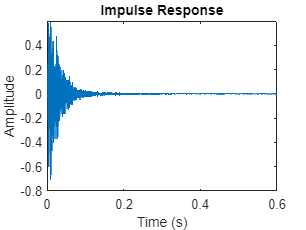

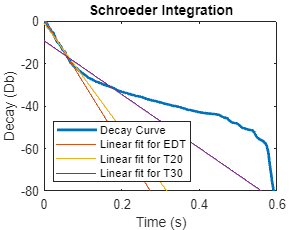


T60 from EDT: 0.202750
T60 from T20: 0.227750
T60 from T30: 0.330125
D50: 0.967715
C50: 34.003424
C80: 49.371661
G: 20.793071


[~,DC,vectorTiempo, AcousticParams.General] = RIR_Analisys(2,RIR.General,room_dim,true);

[~,~,~, AcousticParams.f125] = RIR_Analisys(2,RIR.f125,room_dim,false);
[~,~,~, AcousticParams.f250] = RIR_Analisys(2,RIR.f250,room_dim,false);
[~,~,~, AcousticParams.f500] = RIR_Analisys(2,RIR.f500,room_dim,false);
[~,~,~, AcousticParams.f1k] = RIR_Analisys(2,RIR.f1k,room_dim,false);
[~,~,~, AcousticParams.f2k] = RIR_Analisys(2,RIR.f2k,room_dim,false);
[~,~,~, AcousticParams.f4k] = RIR_Analisys(2,RIR.f4k,room_dim,false);

[~,~,~,SchroederFreq] = CalcRoomModes(room_dim,AcousticParams.General.T60delT20,20)

V = prod(room_dim);
Current_abs = 0.161*V/AcousticParams.General.T60delT20;
DesiredT60 = 0.27
Needed_abs = 0.161*V/DesiredT60;
Offset_abs = Needed_abs-Current_abs;
MaterialAbs.Abs_Panels = 0.8;
MaterialAbs.Wall = 0.02;
Surface = Offset_abs/(MaterialAbs.Abs_Panels-MaterialAbs.Wall)